N = ones(200, 1)

N =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


load sec1-speech.mat
LEN = length(xM)

LEN = 32000

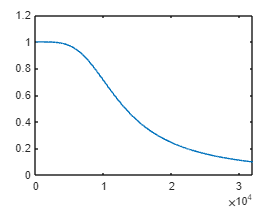

Hlow = ones(1, LEN) * 0;
HIGH = 10000;
for w=1:LEN
    Hlow(w) = HIGH .^ 2  / ((1i * w) .^ 2 + 2 * 0.707 * HIGH * (1i * w) + HIGH .^ 2);
end
plot(abs(Hlow))

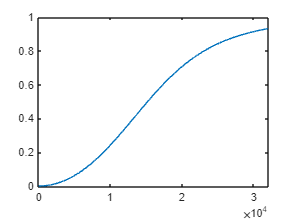

Hhigh = ones(1, LEN) * 0;
LOW = 20000;
DAMP = 0.707;
for w=1:LEN
    MID = 2 * DAMP * LOW * (1i * w);
    SEC = (1i * w) .^ 2;
    Hhigh(w) = (SEC) / (SEC + MID + LOW .^ 2);
end
plot(abs(Hhigh))